clear; close all;

## Open data

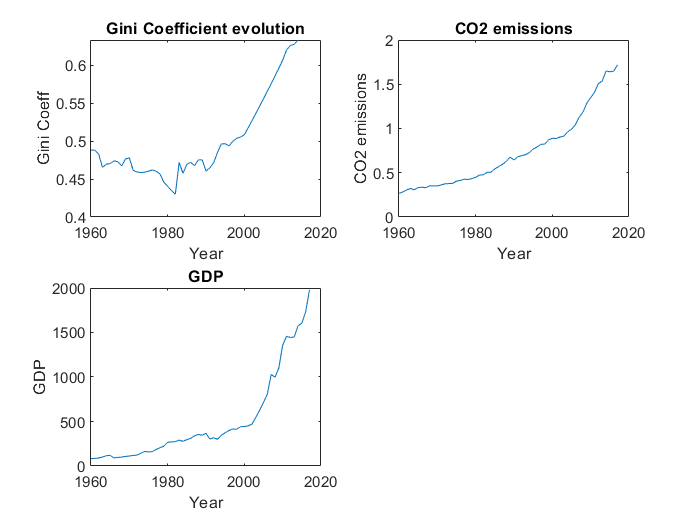

path = "./Data/Gini_index.xlsx";
data = table2array(readtable(path));
time = data(10:end-5,1); gini = data(10:end-5,2);
subplot(221);
plot(time,gini);
title('Gini Coefficient evolution');
xlabel('Year'); ylabel('Gini Coeff');
path = "./Data/india_data.xlsx";
% opts = detectImportOptions(path);
T = readtable(path,"ReadRowNames",true);
data = table2array(T)';
% Finding the first NAN value and taking data upto the instance before it
cut_off = length(data(:,1));
for i = 1:length(data(:,1))
    if (sum(isnan(data(i,:))))
        cut_off = i-1;
        break;
    end
end
time2 = data(1:cut_off,1);
Data = data(1:cut_off,2:end);
subplot(222);
plot(time2,Data(:,1));
title('CO2 emissions'); 
ylabel('CO2 emissions'); xlabel('Year');
subplot(223);
plot(time2,Data(:,2));
title('GDP'); 
ylabel('GDP'); xlabel('Year');

GDP = Data(1:end-3,1);
CO2 = Data(1:end-3,2);
y = CO2;
X = [gini GDP];

## Analysis using OLS

Stabilize Data Values

y = log(y);
X = log(X);
[h1,p1] = adftest(y);

h1 = 0, so difference the series

dlogy = diff(y);

dlogX = X(1:end-1,:);
[h2,p2] = adftest(X(:,1));

h2 = 0, so difference the series

dlogX(:,1) = diff(X(:,1));

[h3,p3] = adftest(X(:,2));

h3 is not 0, but since other 2 are differenced, need to remove one data point

dlogX(:,2) = X(2:end,2);

ols_mdl = fitlm(dlogX,dlogy);
res = ols_mdl.Residuals.Raw;
ols_mdl

ols_mdl = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                   Estimate        SE         tStat        pValue  
                   _________    ________    _________    __________

    (Intercept)     0.065078    0.018354       3.5456    0.00084955
    x1             -0.047764     0.64863    -0.073639       0.94159
    x2               0.02079    0.025749       0.8074       0.42318


Number of observations: 54, Error degrees of freedom: 51
Root Mean Squared Error: 0.0867
R-squared: 0.0137,  Adjusted R-Squared: -0.0249
F-statistic vs. constant model: 0.355, p-value = 0.703


fprintf('R-squared = %.4f, Adjusted R-squared = %.4f \n',ols_mdl.Rsquared.Ordinary,ols_mdl.Rsquared.Adjusted);

R-squared = 0.0137, Adjusted R-squared = -0.0249 


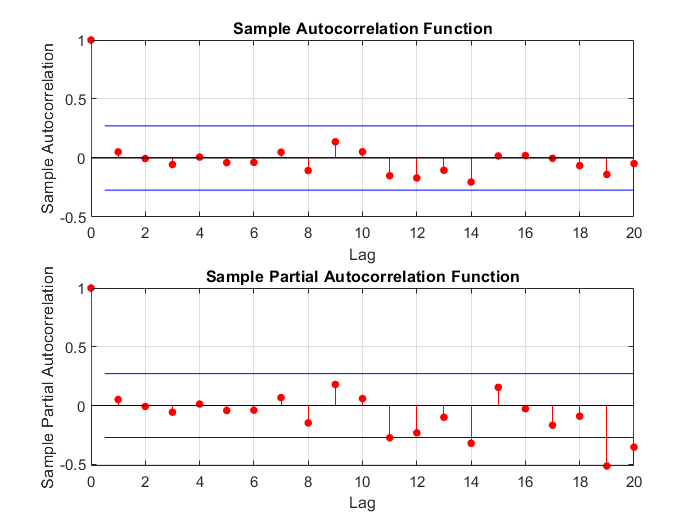

figure;
subplot(211); autocorr(res);
subplot(212); parcorr(res);

Has some PACF at higher lags, but can safely ignore them since our total time is ~ 2*such periods

[hres1,pres1] = lbqtest(res);
disp('Whiteness Test for Residuals results');

Whiteness Test for Residuals results


disp(hres1);disp(pres1);

   0

    0.8872



Hence, Residuals are white

[h_adres1,p_adres1] = adtest(res);
disp('Gaussianity Test for Residuals results');

Gaussianity Test for Residuals results


disp(h_adres1);disp(p_adres1);

   1

    0.0084



Gaussianity rejected! Residuals are not Gaussian

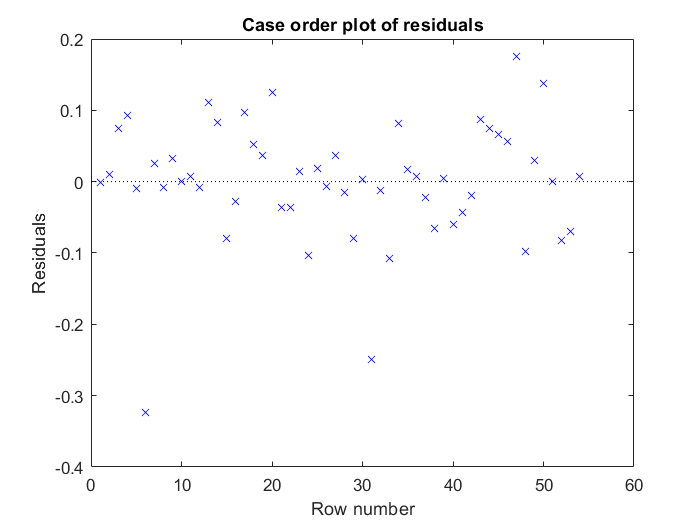

figure;
plotResiduals(ols_mdl,'caseorder');

Exhibits some heteroskedasticity

## Feasible Generalized least squares

[coeff,se,EstCoeffCov] = fgls(dlogX,dlogy,'innovMdl','HC0','display','final');


OLS Estimates:

       |  Coeff     SE   
-------------------------
 Const |  0.0651  0.0184 
 x1    | -0.0478  0.6486 
 x2    |  0.0208  0.0257 

FGLS Estimates:

       |  Coeff     SE   
-------------------------
 Const |  0.0662  0.0009 
 x1    | -0.0974  0.0544 
 x2    |  0.0216  0.0009 


## OLS Analysis without differencing

ols_mdl2 = fitlm(X,y);
res2 = ols_mdl2.Residuals.Raw;
ols_mdl2

ols_mdl2 = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)      6.4462     0.25198     25.582    3.9611e-31
    x1             -0.14444     0.40652    -0.3553       0.72381
    x2                 1.66    0.082107     20.217     2.711e-26


Number of observations: 55, Error degrees of freedom: 52
Root Mean Squared Error: 0.169
R-squared: 0.962,  Adjusted R-Squared: 0.96
F-statistic vs. constant model: 650, p-value = 1.63e-37


fprintf('R-squared = %.4f, Adjusted R-squared = %.4f \n',ols_mdl2.Rsquared.Ordinary,ols_mdl2.Rsquared.Adjusted);

R-squared = 0.9615, Adjusted R-squared = 0.9601 


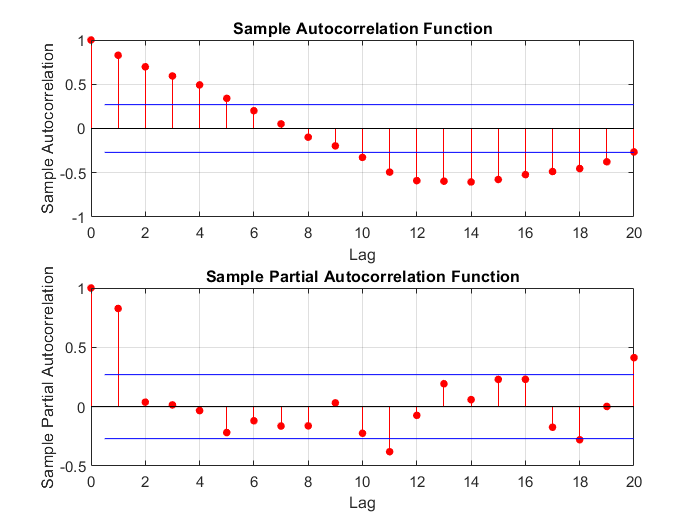

figure;
subplot(211); autocorr(res2);
subplot(212); parcorr(res2);

% Slowly dying ACF, and immediately dying PACF => MA(1)
[hres2,pres2] = lbqtest(res2);
% Residuals are correlated!

## FGLS again

Not continuing this. However the procedure: fit an MA model to res2, convert to AR using arma2ar. Then find significant terms in AR, denote number of terms as p. Pass that p to FGLS [coeff2,se2,EstCoeffCov2] = fgls(X,y,'arlags',1,'display','final');

## BOD x Gini

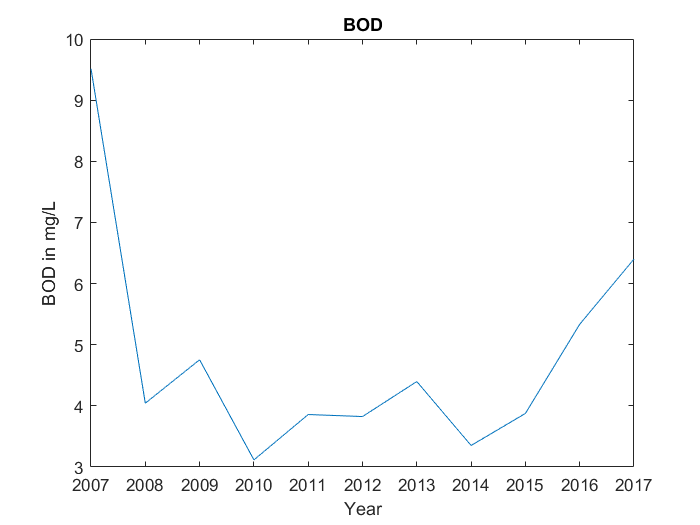

bod = xlsread("./Data/BOD.xlsx","Averaged");
figure;
plot(bod(1,:),bod(2,:));
title("BOD"); ylabel("BOD in mg/L"); xlabel("Year");

% Since sample size is small (~10) not subjecting it to adftest
bod_data = log(bod(2,1:end-4))'; % because other data till 2014
% Resize matrices
idx = find(time==2007);
dlogy_new = dlogy(idx:end);
dlogX_new = [bod_data,dlogX(idx:end,2)];

% run ols
ols_mdl_bod = fitlm(dlogX,dlogy);
res_bod = ols_mdl_bod.Residuals.Raw;
ols_mdl_bod

ols_mdl_bod = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                   Estimate        SE         tStat        pValue  
                   _________    ________    _________    __________

    (Intercept)     0.065078    0.018354       3.5456    0.00084955
    x1             -0.047764     0.64863    -0.073639       0.94159
    x2               0.02079    0.025749       0.8074       0.42318


Number of observations: 54, Error degrees of freedom: 51
Root Mean Squared Error: 0.0867
R-squared: 0.0137,  Adjusted R-Squared: -0.0249
F-statistic vs. constant model: 0.355, p-value = 0.703


fprintf('R-squared = %.4f, Adjusted R-squared = %.4f \n',ols_mdl_bod.Rsquared.Ordinary,ols_mdl_bod.Rsquared.Adjusted);

R-squared = 0.0137, Adjusted R-squared = -0.0249 


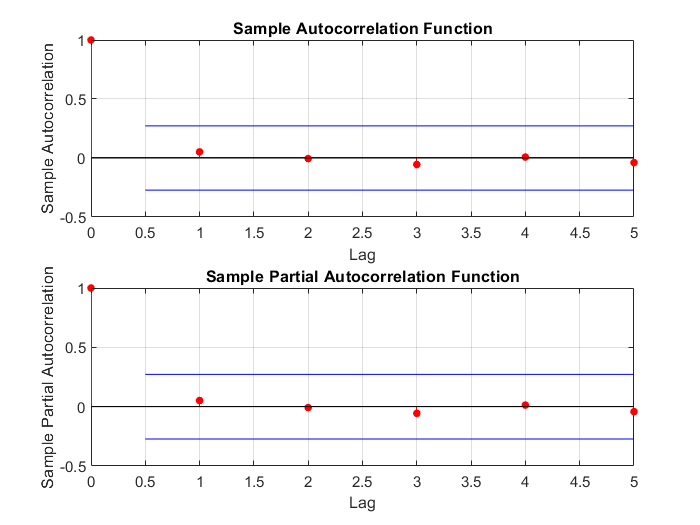

figure;
subplot(211); autocorr(res_bod,"NumLags",5);
subplot(212); parcorr(res_bod,"NumLags",5);

No autocorrelation effects!

[hresBOD,presBOD] = lbqtest(res_bod);
disp('Whiteness Test for Residuals results');

Whiteness Test for Residuals results


disp(hresBOD);disp(presBOD);

   0

    0.8872



Hence, Residuals are white

[h_adres_BOD,p_adres_BOD] = adtest(res_bod);
disp('Gaussianity Test for Residuals results');

Gaussianity Test for Residuals results


disp(h_adres_BOD);disp(p_adres_BOD);

   1

    0.0084



Gaussianity rejected! Residuals are not Gaussian

figure;
plotResiduals(ols_mdl_bod,'caseorder');

Exhibits some heteroskedasticity

% run fgls
[coeff_BOD,se_BOD,EstCoeffCov_BOD] = fgls(dlogX_new,dlogy_new,'innovMdl','HC0','display','final');


OLS Estimates:

       |  Coeff     SE   
-------------------------
 Const |  0.6433  0.4334 
 x1    | -0.2964  0.2146 
 x2    | -0.4297  0.4274 

FGLS Estimates:

       |  Coeff     SE   
-------------------------
 Const |  0.5335  0.4380 
 x1    | -0.2589  0.2118 
 x2    | -0.3190  0.3938 
